## Set up

clc
clear
clf
rng(16);

### Preprocessing

FullSet = readtable("Data\Process_data\measured_data_combined.csv");
X = FullSet(:,2:3);
X.f_LO_measured = FullSet.f_LO_measured;
X.f_LE_measured = FullSet.f_LE_measured;
X.c_RaffP_measured = FullSet.c_RaffP_measured;
X.c_RaffS_measured = FullSet.c_RaffS_measured;
X.c_BO_measured = FullSet.c_BO_measured;
% SmarketD.Direction = categorical(SmarketD.Direction);
% summary(SmarketD);
% Smarket = normalize(SmarketD(:,3:end-1));
% Smarket.Direction = SmarketD.Direction;
X_N = normalize(X);

y = FullSet.fault_state;



% Apply LDA for dimensionality reduction on the training data
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X_N, y); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Project training and testing data onto the LDA components
X_reduced = table2array(X_N) * projection_matrix;

k_values = 1:100;
cv_accuracies = zeros(1,length(k_values));
k_fold = 10;
cv = cvpartition(length(y), 'KFold', k_fold);

for i = 1:length(k_values)
    k = k_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        trn = training(cv, fold);
        tst = test(cv, fold);
        
        X_train = X_reduced(trn, :);
        y_train = y(trn);
        X_test = X_reduced(tst, :);
        y_test = y(tst);
        
        % Train kNN for current k
        kNN_model = fitcknn(X_train, y_train, 'NumNeighbors', k);
        
        y_pred = predict(kNN_model, X_test);
        
        accuracy = sum(y_pred == y_test) / length(y_test);
        accuracies(fold) = accuracy;
        
    end
    
    cv_accuracies(i) = mean(accuracies);
end
[M, I] = max(cv_accuracies);
best_k = k_values(I);

disp(['Best k: ', num2str(best_k)]);

Best k: 1


disp(['Cross validation accuracy with best k: ', num2str(M)]);

Cross validation accuracy with best k: 0.99951



final_kNN_model = fitcknn(X_train,y_train, 'NumNeighbors', best_k);

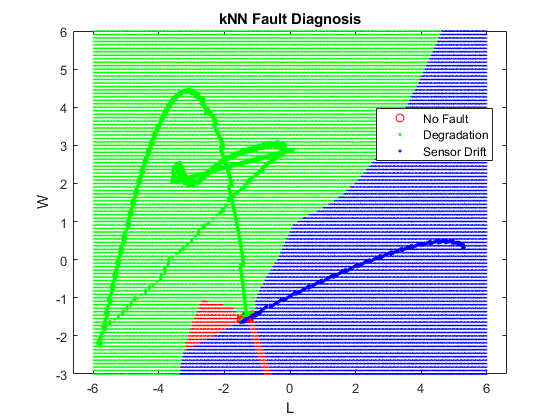

gscatter(X_reduced(:, 1), X_reduced(:, 2), y, 'rgb', 'o..');
title('kNN Fault Diagnosis');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-6, 6, 500), linspace(-3,6,100)); ...
L = L(:);
W = W(:);
pred = final_kNN_model.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
legend('No Fault', 'Degradation', 'Sensor Drift', '', '', '');
hold off; 
print('Results/Toy/kNN/kNN_visual', '-dpng', '-r600')


% Predict on the test data and calculate the confusion matrix
y_pred = predict(final_kNN_model, X_test);
C = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

        3110           0           0
           3        2938           0
           0           0        2589



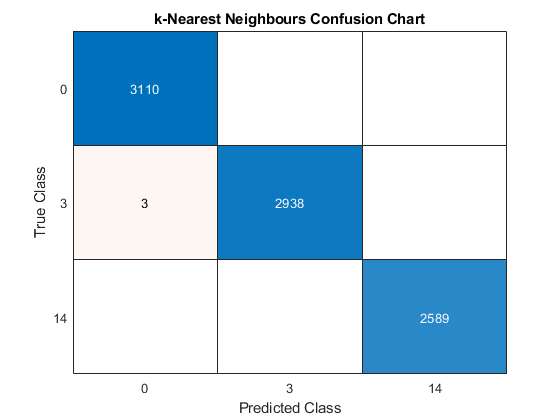


confusionchart(y_test, y_pred)
title('k-Nearest Neighbours Confusion Chart');
print('Results/Toy/kNN/kNN_confchart', '-dpng', '-r600')

mean(y_pred == y_test)

ans = 0.9997

Predictions

[ldaPredClass, ldaPredPosterior] = predict(final_kNN_model,X_test);
mean(ldaPredClass == y_test)

ans = 0.9997

50% threshold

sum(ldaPredPosterior(:,1) >= 0.5)

ans = 3113

sum(ldaPredPosterior(:,1) < 0.5)

ans = 5527

ldaPredPosterior(1:20,1).'

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


ldaPredClass(1:20,1).'

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% 90 %
sum(ldaPredPosterior(:,1) >= 0.9)

ans = 3113